# Linear Control Design II - Group Work Problem Module 13

## Description

Consider the airplane model (MIMO model).

% System matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
    0.598  -0.115  -0.0318  0;
    -3.050   0.388  -0.4650  0;
    0       0.0805  1       0]

A =       -0.0558      -0.9968       0.0802       0.0415
        0.598       -0.115      -0.0318            0
        -3.05        0.388       -0.465            0
            0       0.0805            1            0


B = [0.00729 1e-5; -0.475 0.123; 0.153 1.063; 0 0]

B =       0.00729        1e-05
       -0.475        0.123
        0.153        1.063
            0            0


C = [0 1 0 0;0 0 0 1]

C =      0     1     0     0
     0     0     0     1


D = [0;0];
damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -3.29e-02 + 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -3.29e-02 - 9.47e-01i     3.48e-02       9.47e-01          3.04e+01    
 -5.63e-01                 1.00e+00       5.63e-01          1.78e+00    
 -7.28e-03                 1.00e+00       7.28e-03          1.37e+02    


**Problem 1**

Is the system observable? Is it detectable?

% Fill in your answer here:

Mo=obsv(A,C);
if rank(Mo)==size(A,1)
    disp('The System is observable')
else
    disp('The System is not observable')
end

The System is observable


**Problem 2**

In module 10 multivariable state feedback controller for the aircraft. The closed-loop continuous eigenvalues were:


$$\lambda=\left\{\matrix{-0.5\cr-0.6\cr-0.5\pm0.5j}\right.$$


Design a discrete time observer for the system and use the sampling period $Ts=0.1\text{s}$. Find the observer gain matrix **L** that assigns the eigenvalues of the estimation error dynamics to be 4-5 times faster than those of the closed-loop system (in continuous time). Use the Matlab function *place()* and remember that an observer can be designed by solving the dual problem of controller design.

Check the eigenvalues of the estimation error.

% Fill in your answer here:
Ts = 0.1;
[F,G] = c2d(A,B,Ts)

F =       0.99025     -0.09852     0.008162    0.0041326
     0.059681      0.98554   -0.0028461   0.00012395
     -0.29562     0.052509      0.95329  -0.00061999
    -0.014699     0.010396     0.097656      0.99998


G =     0.0031376  -0.00017599
    -0.047181      0.01206
     0.013694      0.10412
    0.0005229    0.0052907


lambda = [-0.5 -0.6 -0.5-0.5j -0.5+0.5j];
P_obsv_d = exp(5*lambda*Ts);

L=place(F',C', P_obsv_d)'

L =       0.14764     -0.46951
      0.30553     -0.12927
     -0.32822        1.305
    -0.025207      0.59473


log(eig(F-L*C))/Ts

ans =          -2.5 +        2.5i
         -2.5 -        2.5i
         -2.5 +          0i
           -3 +          0i


**Problem 3**

Add the observer to the open loop Simulink model of the aircraft and carry out a simulation with the function on Figure 1 at both inputs, but one at a time. Plot the states, the state estimates and the estimation error.

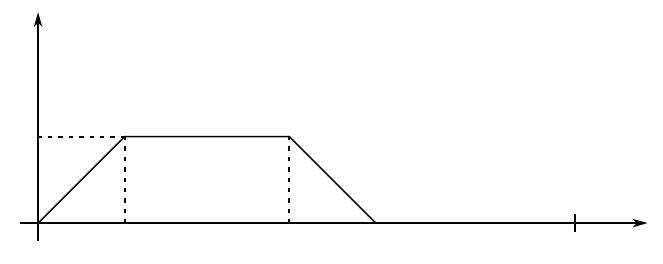


$$Figure\,1: Input\,signal\,for\,the\,closed\,loop\,system.$$


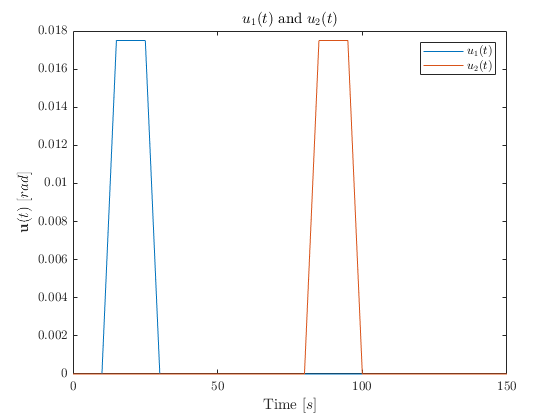

% Fill in your answer here:
t = 0:0.1:150;

% Input funtion of interest
U1 = t(1:50)*0.0175/5;
U2 = t(51:150)*0+0.0175;
U3 = 0.0175-U1;
% Spacing
U4 = 0*t(1:100);
U5 = 0*t(1:800);
U6 = 0*t(1001:end);
U7 = 0*t(301:end);

u1 = [U4 U1 U2 U3 U7];
u2 = [U5 U1 U2 U3 U6];

inp = [t' u1' u2'];
xh0 = [0.015;-0.03;-0.08;-0.7]';
x0 = [0 0 0 0]';

sim('Mdl_13_OpenLoop_w_observer.slx',t(end),[],inp)
pTime = 150;
lbl = labels(4,2,2,{'$\beta$ (Slip Slide angle)','$r$ (Yaw rate)',...
    '$p$ (Roll rate)','$\varphi$ (Roll angle)'},{'rad','rad/s','rad/s','rad'},...
    {'rad','rad'},{});
figure, plot(t_olwo, y_olwo.signals(6).values),xlabel(lbl.time),ylabel([lbl.u_vec lbl.uUnits{1}])
title([lbl.u{1} ' and ' lbl.u{2}]),legend(lbl.u{1}, lbl.u{2})

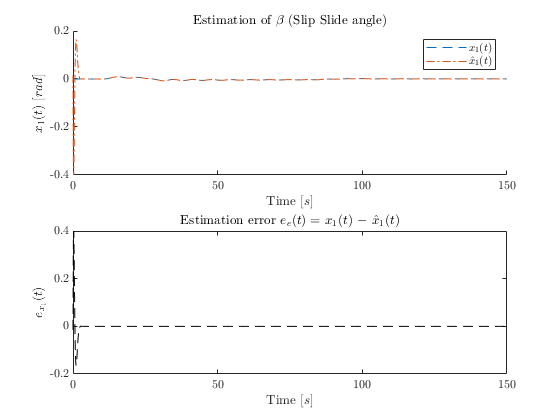

figure, subplot(2,1,1),hold on, num = 1;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
axis([ 0 pTime -0.4 0.2])
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num}),
xlabel(lbl.time), ylabel(lbl.xU{num})
subplot(2,1,2)
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}]; axis([ 0 pTime -0.2 0.4])
title(['Estimation error ' e]), %legend(e),
xlabel(lbl.time), ylabel(['$e_{x_' num2str(num) '}(t)$'])

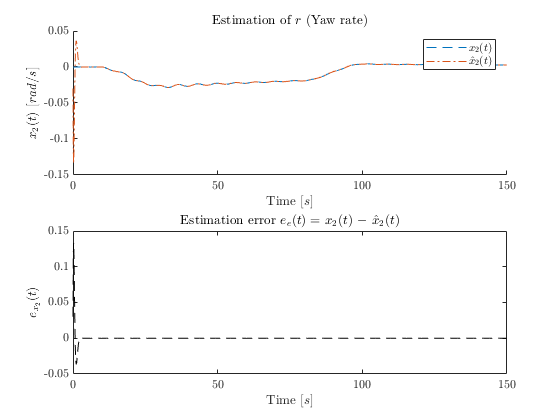

figure,subplot(2,1,1); hold on, num = 2;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num}),
xlabel(lbl.time), ylabel(lbl.xU{num})
subplot(2,1,2)
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];  
title(['Estimation error ' e]), %legend(e),
xlabel(lbl.time), ylabel(['$e_{x_' num2str(num) '}(t)$'])

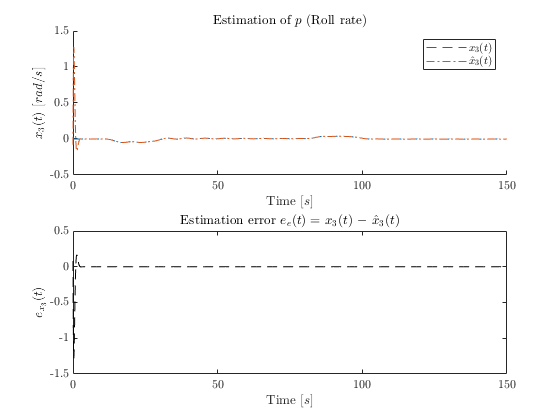

figure,subplot(2,1,1), hold on, num = 3;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num}),
xlabel(lbl.time), ylabel(lbl.xU{num})
subplot(2,1,2)
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];  
title(['Estimation error ' e]), %legend(e),
xlabel(lbl.time), ylabel(['$e_{x_' num2str(num) '}(t)$'])

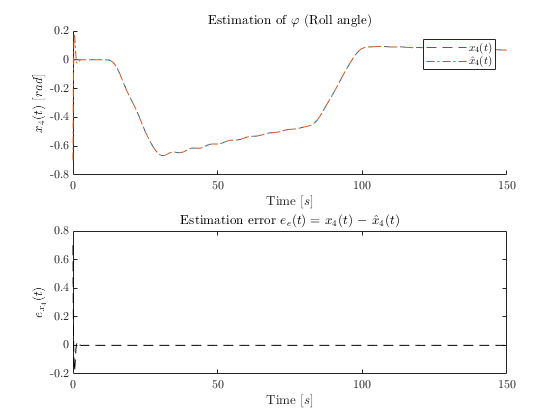

figure,subplot(2,1,1), hold on, num = 4;
plot(t_olwo(t_olwo<pTime), y_olwo.signals(2).values((t_olwo<pTime),num),'--') % x1
plot(t_olwo(t_olwo<pTime), y_olwo.signals(4).values((t_olwo<pTime),num),'-.')% x1_h
title(['Estimation of ' lbl.xN{num}]), legend(lbl.x{num},lbl.xh{num}),
xlabel(lbl.time), ylabel(lbl.xU{num})
subplot(2,1,2)
plot(t_olwo(t_olwo<pTime), y_olwo.signals(5).values((t_olwo<pTime),num),'k--')% e = x1-x1_h
e = ['$e_e(t) =$ ' lbl.x{num} ' $-$ ' lbl.xh{num}];  
title(['Estimation error ' e]), %legend(e),
xlabel(lbl.time), ylabel(['$e_{x_' num2str(num) '}(t)$'])

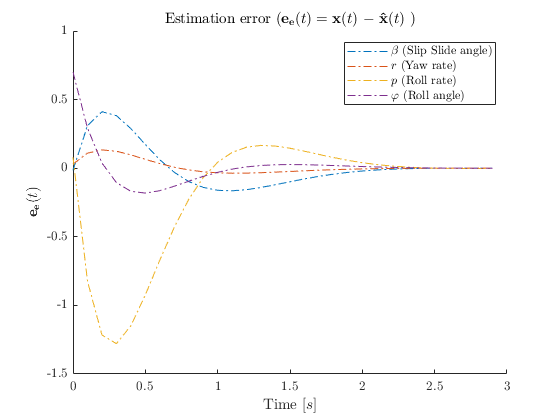

figure, hold on
plot(t_olwo(t_olwo<3), y_olwo.signals(5).values(t_olwo<3,:),'-.')
title(['Estimation error $(\mathbf{e_e}(t) =$ ' lbl.x_vec ' $-$ ' lbl.xh_vec ' $)$' ])
legend(lbl.xN), xlabel(lbl.time), ylabel('$\mathbf{e_e}(t)$')

**Problem 4**

Add the discrete controller designed in the module 10 to the Simulink model and instead of using the true states of the system, use their estimates provided by the observer. Carry out simulations and plot the states, the state estimates, the estimation error, the outputs and the control signals. Compare the performance of the closed-loop systems with and without the observer.

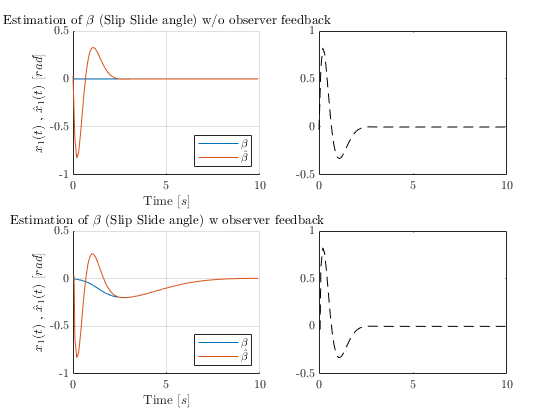

% Fill in your answer here:
l_cld = exp(lambda*Ts);
K = place(F,G,l_cld);
xh0 = [0.015;-0.03;-0.08;-0.7]*2;
h = 1;
sim('Mdl_13_CloseLoop_w_observer.slx',t(end),[],inp)
lbl.xvar = {'$\beta$','$r$','$p$','$\varphi$'};
lbl.xhvar = {'$\hat{\beta}$','$\hat{r}$','$\hat{p}$','$\hat{\varphi}$'};
pTime = 10;
f1 = figure(); subplot(2,2,1),  num = 1;
hold on; title(['Estimation of ' lbl.xN{num} ' w/o observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')
f2 = figure(); subplot(2,2,1),  num = 2;
hold on; title(['Estimation of ' lbl.xN{num} 'w/o observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')
f3 = figure(); subplot(2,2,1),  num = 3;
hold on; title(['Estimation of ' lbl.xN{num} 'w/o observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')
f4 = figure(); subplot(2,2,1),  num = 4;
hold on; title(['Estimation of ' lbl.xN{num} 'w/o observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')
h = 0;
sim('Mdl_13_CloseLoop_w_observer.slx',t(end),[],inp)
figure(f1); subplot(2,2,3),  num = 1;
hold on; title(['Estimation of ' lbl.xN{num} ' w observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')

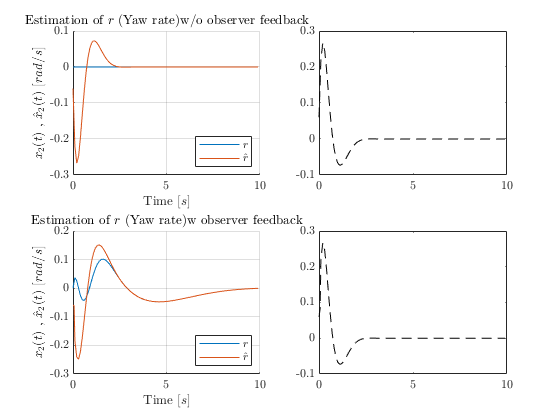

figure(f2); subplot(2,2,3),  num = 2;
hold on; title(['Estimation of ' lbl.xN{num} 'w observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')

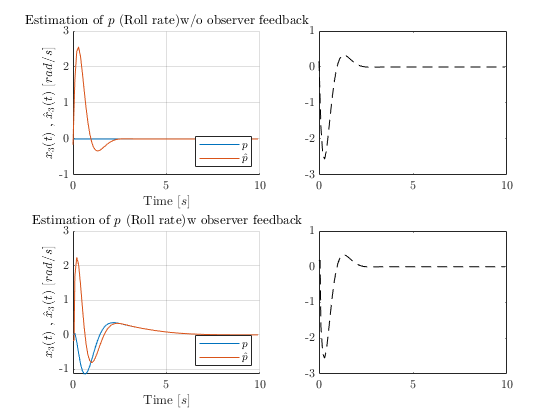

figure(f3); subplot(2,2,3),  num = 3;
hold on; title(['Estimation of ' lbl.xN{num} 'w observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')

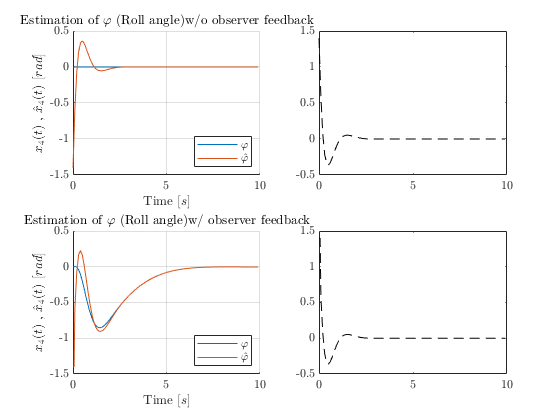

figure(f4); subplot(2,2,3),  num = 4;
hold on; title(['Estimation of ' lbl.xN{num} 'w/ observer feedback'])
plot(t_clwo(t_clwo<pTime), y_clwo.signals(2).values(t_clwo<pTime,num))
plot(t_clwo(t_clwo<pTime), y_clwo.signals(4).values(t_clwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),
plot(t_clwo(t_clwo<pTime), y_clwo.signals(5).values(t_clwo<pTime,num),'k--')

**Problem 5**

Do the estimations obtained from the observer depend on how good the controller is? Can we estimate any of the states if the system is very fast or unstable?

% Fill in your answer here:



**Problem 6**

Repeat Problem 2-4 using the controller with integral action.

% Fill in your answer here:
Fi = [F zeros(size(G));-C eye(2)]

Fi =       0.99025     -0.09852     0.008162    0.0041326            0            0
     0.059681      0.98554   -0.0028461   0.00012395            0            0
     -0.29562     0.052509      0.95329  -0.00061999            0            0
    -0.014699     0.010396     0.097656      0.99998            0            0
            0           -1            0            0            1            0
            0            0            0           -1            0            1


Gi = [G; zeros(2)]

Gi =     0.0031376  -0.00017599
    -0.047181      0.01206
     0.013694      0.10412
    0.0005229    0.0052907
            0            0
            0            0


Ci = [C  zeros(2)]

Ci =      0     1     0     0     0     0
     0     0     0     1     0     0


l_cli=[-.5 -.6 -.5+1i -.5-1i -.7 -.7];
l_clid = exp(Ts*l_cli);
K1 = place(Fi,Gi,l_clid);
K_l = K1(:,1:(end-2))

K_l =       -11.243      -3.9759    -0.033967      0.54361
      -20.379      -2.8737       1.3616       2.9301



Ki  = -K1(:,(end-1):end)

Ki =       -1.1559     0.030297
      -2.0633      0.11719



cl_l = log(eig(Fi-Gi*K1))/Ts

cl_l =          -0.5 +          1i
         -0.5 -          1i
         -0.5 +          0i
         -0.6 +          0i
         -0.7 +  8.793e-14i
         -0.7 -  8.793e-14i


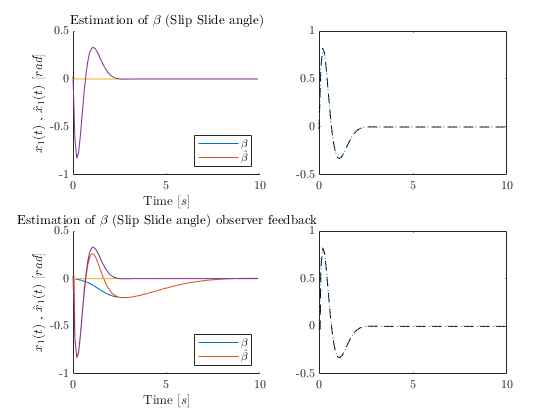

h = 1;
sim('Mdl_13_CloseLoopIntegrator_w_observer.slx',t(end),[],inp)
pTime = 10;
figure(f1); subplot(2,2,1),  num = 1;
hold on; title(['Estimation of ' lbl.xN{num}])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')
figure(f2); subplot(2,2,1),  num = 2;
hold on; title(['Estimation of ' lbl.xN{num}])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')
figure(f3); subplot(2,2,1),  num = 3;
hold on; title(['Estimation of ' lbl.xN{num}])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')
figure(f4); subplot(2,2,1),  num = 4;
hold on; title(['Estimation of ' lbl.xN{num}])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,2),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')
h = 0;
sim('Mdl_13_CloseLoop_w_observer.slx',t(end),[],inp)
figure(f1); subplot(2,2,3),  num = 1;
hold on; title(['Estimation of ' lbl.xN{num} ' observer feedback'])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4), hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')

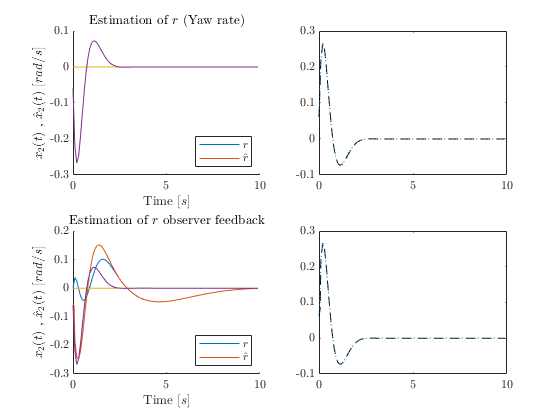

figure(f2); subplot(2,2,3),  num = 2;
hold on; title(['Estimation of ' lbl.xvar{num} ' observer feedback'])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')

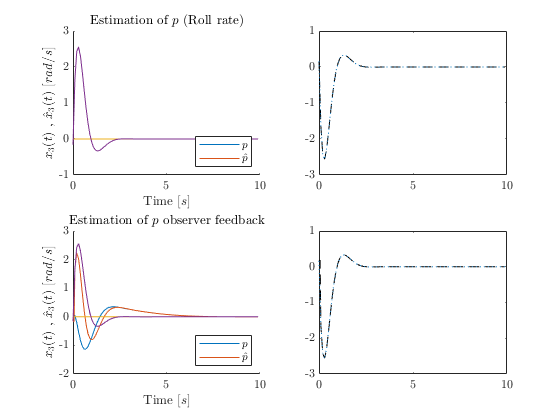

figure(f3); subplot(2,2,3),  num = 3;
hold on; title(['Estimation of ' lbl.xvar{num} ' observer feedback'])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')

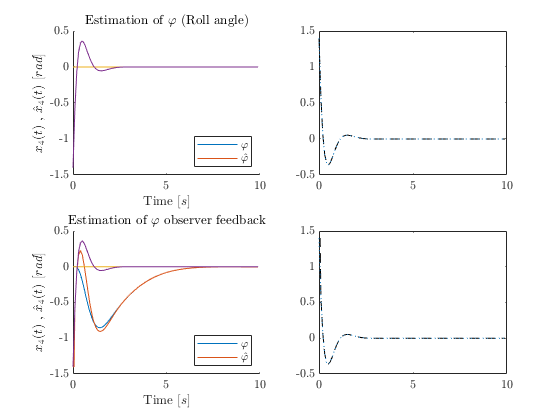

figure(f4); subplot(2,2,3),  num = 4;
hold on; title(['Estimation of ' lbl.xvar{num} ' observer feedback'])
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(2).values(t_cliwo<pTime,num))
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(4).values(t_cliwo<pTime,num))
xlabel(lbl.time),ylabel([lbl.x{num} ' , ' lbl.xhU{num}])
legend(lbl.xvar{num}, lbl.xhvar{num},'Location','southeast'), grid
subplot(2,2,4),hold on
plot(t_cliwo(t_cliwo<pTime), y_cliwo.signals(5).values(t_cliwo<pTime,num),':')

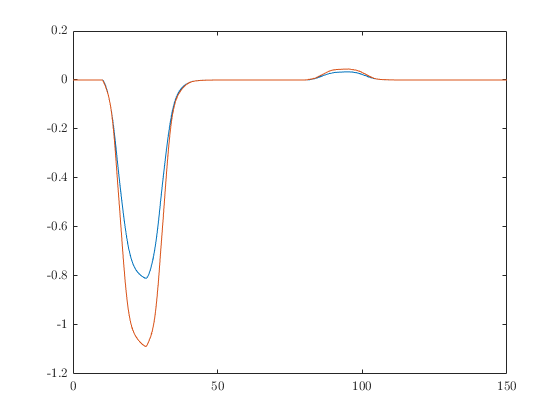

figure
plot(t_cliwo,y_cliwo.signals(6).values)

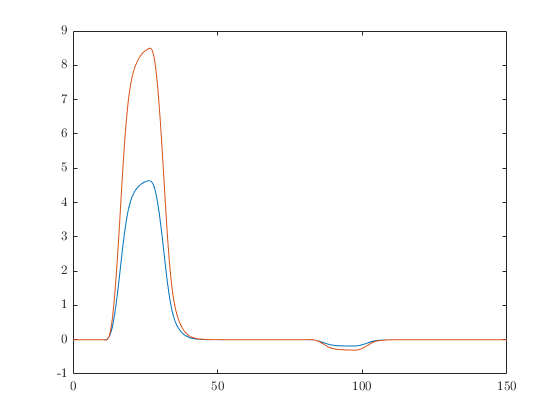

figure
plot(t_cliwo, y_cliwo.signals(7).values)